**EE-414 Speech Processing Lab**

**Lab-7**

**AIM**

- To understand the limitation of DTFT for the spectral analysis of speech.

- To understand the development of short-term Fourier transform (STFT) representation.

- To understand the difference in the nature of linear and log magnitude spectra.

- To understand the difference among the spectra of voiced, unvoiced and silence regions of speech.

- To plot the STFT of a speech signal.

- To understand the difference between true and convolved spectra.

- To understand the effect of rectangular, Hamming and Hanning window functions on short term spectral analysis.

- To understand the effect of frame size on short term spectral analysis

**THEORY**

The short term time domain analysis is useful for computing the time domain features at the gross level like energy,  zero crossing rate and autocorrelation. The different frequency or spectral components that are present in the speech signal are not directly apparent in the time domain. Hence we need to go for frequency domain representation using Fourier representation. The conventional Fourier representation is inadequate to provide information about the time varying nature of spectral information present in speech. Hence the need for short term version of Fourier transform, termed more commonly as Short term Fourier Transform (STFT).

**DTFT : **

 From digital signal processing , to obtain the frequency domain representation we use discrete time Fourier transform (DTFT). If X(w) is the discrete time Fourier Transform(DTFT)  of  x(n),a discrete time signal, then its DTFT is given by

 

As given in equn (1), X(w) is continuous function of frequency and hence cannot be computed on a digital signal processor or machine. To make it possible discrete version of the DTFT termed as discrete Fourier transform (DFT) is defined where DFT is obtained by uniformly sampling X(w) is given by

 

where     , k=0,1,....(N-1), where 'N' is the number of samples of X(w). The value of 'N' is chosen such that, the reconstructed sequence x(n) in the time domain is free from aliasing. For this the condition is 'N' should be greater than or equal to the length of x(n). 

**PROCEDURE**

Record (16kHz, 16bit) the word “**speech signal**”; truncate long silence regions. 

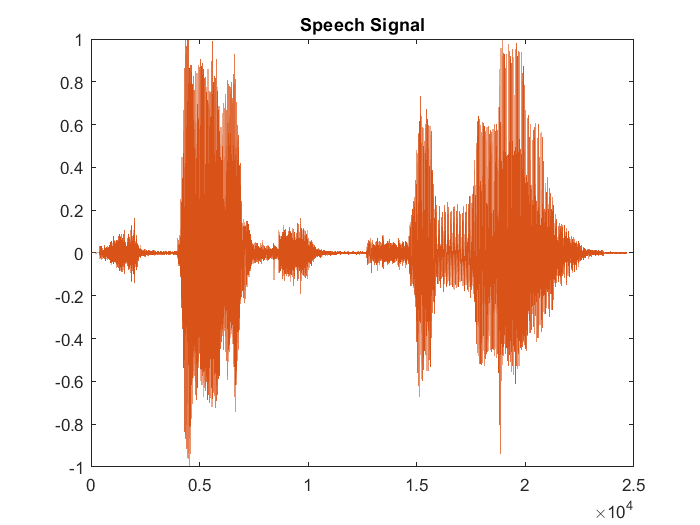

[y,Fs] = audioread('speech_signal.wav');
sound(y,Fs);
plot(y)
title('Speech Signal');

A. DTFT of and its limitation:

- Plot the linear and log magnitude spectrum for the entire speech. 

max_value = max(abs(y))

max_value =     0.9936    0.9936


y = y/max_value

y =          0
   -0.1536
         0
   -0.1536
         0
         0
         0
         0
         0
         0


t = 1/Fs:1/Fs:(length(y)/Fs)

t =     0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0024    0.0024    0.0025    0.0026    0.0026    0.0027    0.0028    0.0028    0.0029    0.0029    0.0030    0.0031    0.0031


figure();
subplot(3,1,1)
plot(t,y)
title('Speech Signal in time domain')
dfty = abs(fftshift(fft(y)))

dfty =     0.0021
    0.0077
    0.0046
    0.0092
    0.0073
    0.0033
    0.0047
    0.0035
    0.0064
    0.0039


leny = length(y)

leny = 24662

len = length(dfty)

len = 24662

tt = linspace(1/Fs,Fs,length(dfty))

tt = 	1.0e+04 *

    0.0000    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0030    0.0031    0.0032


subplot(3,1,2)
plot(tt,dfty)
title('Linear MagnitudeSpectrum')
dftylog = 10*log10(dfty)

dftylog =   -26.7696
  -21.1602
  -23.3292
  -20.3495
  -21.3674
  -24.7560
  -23.3004
  -24.5182
  -21.9669
  -24.1256


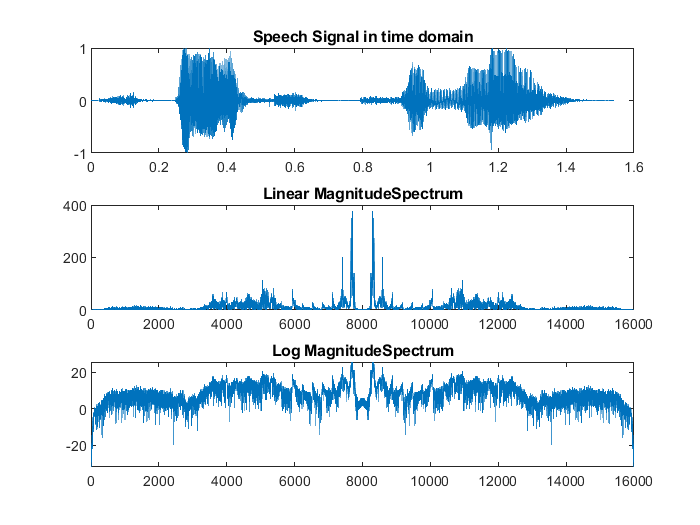

subplot(3,1,3)
plot(tt,dftylog)
title('Log MagnitudeSpectrum')

**OBSERVATIONS:**

**It can be observed that both the small and large magnitude frequency components are visible in the log magnitude spectrum compared to the linear magnitude spectrum.**

2. Plot log-magnitude spectrum of voiced, unvoiced and silence regions in the recorded speech and explain the difference between log-spectrum of all three cases.

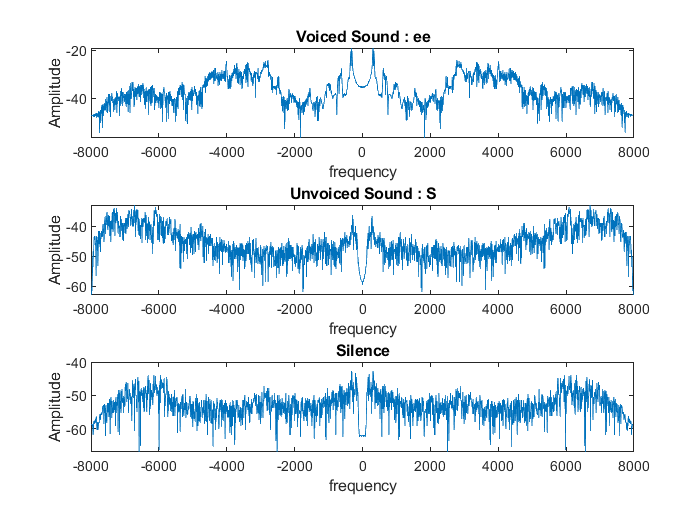

fs = 16000;

%Voiced Speech --> 'ee'
t1=0.299*fs : 0.433*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y(t1);
dF1= fs/length(t1); % Time resolution 
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(3,1,1)
plot(f1,10*log10(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Voiced Sound : ee');

%Unvoiced Speech --> 'S'
t2=0.019*fs : 0.158*fs ; % Time Observed From Wavesurfer
t2=round(t2);
x2=y(t2);
dF2= fs/length(t2); % Time resolution 
f2=-fs/2:dF2:fs/2-dF2 ; % hz pers sample
X2=fftshift(fft(x2)); % Fourier transform
subplot(3,1,2)
plot(f2,10*log10(abs(X2)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Unvoiced Sound : S');

%Silence 
t3=0.660*fs : 0.789*fs ; % Time Observed From Wavesurfer
t3=round(t3);
x3=y(t3);
dF3= fs/length(t3); % Time resolution 
f3=-fs/2:dF3:fs/2-dF3 ; % hz pers sample
X3=fftshift(fft(x3)); % Fourier transform
subplot(3,1,3)
plot(f3,10*log10(abs(X3)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Silence');

**3. Comment on the limitation of DTFT.**

1) In case of speech the large magnitude frequency components dominate in the linear magnitude spectrum to give a false picture of small magnitude frequency components. To reduce the dynamic range, the logarithmic version of the magnitude spectrum is taken. In case of log magnitude spectrum both large and small magnitude frequency components are visible.

2) The magnitude spectrum gives only the  gross information of the frequency components present in the speech signal. However, this spectrum does not tell us when a particular frequency component is present i.e the timing information is completely lost. 

3) As speech is a non-stationery signal i.e the frequency components change with time, we need a representation that will give time varying spectral information as well.

4) In c part, spectrum of voiced, unvoiced and silence is plotted and it can be observed that nature of spectrum is different for all these three segments as speech ia a combination of such time-varying spectrums. 

 Thus it is not the correct way of computing the spectrum of non-stationery signal.

**B. Need for Short Time Fourier Transform(STFT):**

- How can you solve the above problem using STFT? Plot the STFT of one speech frame at the centre of above three regions. Write your observations.

**Theory :**

In short term processing, speech is processed is blocks of 10-30 ms with a shift of 10 ms. and the DTFT is computed using DFT for that block.  Their process is repeated for all the blocks of speech signal and all the spectra computed are stacked together as a function of time and frequency to observe the time varying spectra. To accommodate the time varying nature of this spectra, the DTFT equation is defined as given below

    

where ***W(n)*** is the window function for short term processing. Now the spectral amplitude and phase are function of both frequency and time where as it was only function of frequency in the earlier case of DTFT. ***x(m).w(n-m)*** represents the  window segment around the time instant ***'******n'.*** Hence ***X(w,n)*** at ***'n'*** represents the spectrum of the speech segment present around it. When we shift ***'n'***, then correspondent ***X(w,n)*** also changes. Thus giving visualization of the time varying spectra of speech. Since such a time-spectral is computed using short term processes, ***X(w,n)*** is termed as Short Term Fourier Transform (STFT).

Spectrograms:

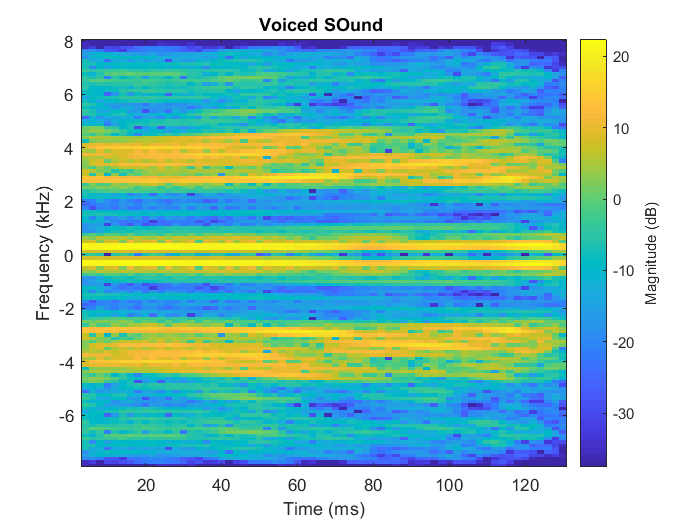

figure();
stft(x1,fs)
title('Voiced SOund ')

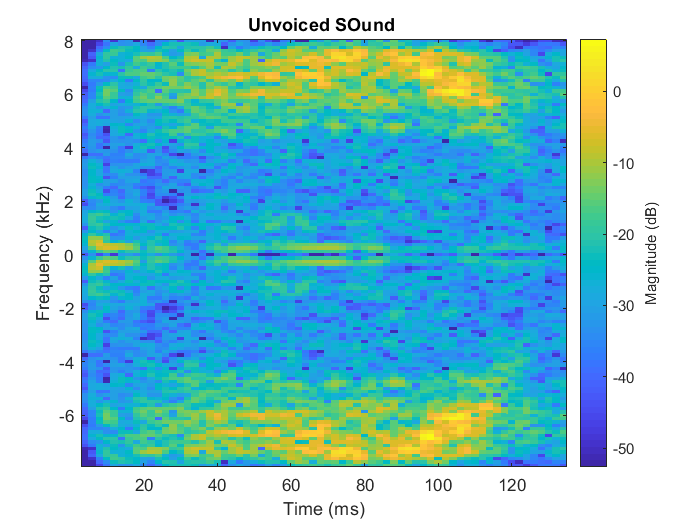

figure();
stft(x2,fs)
title('Unvoiced SOund ')

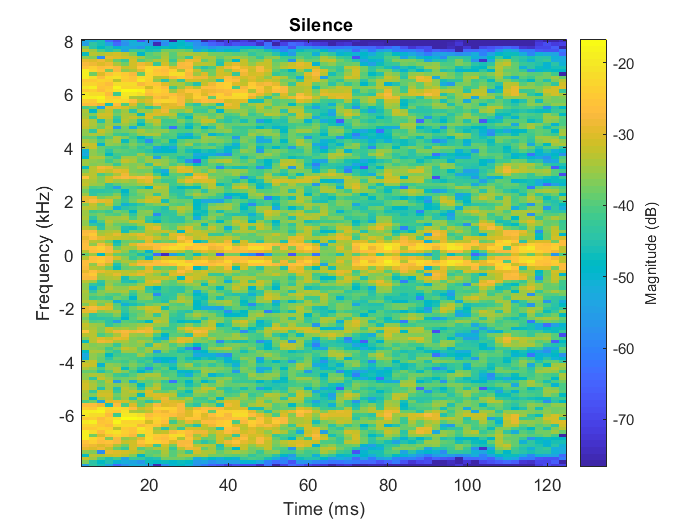

figure();
stft(x3,fs)
title('Silence ')

**Comments and Observations:**

- Time varying spectra of speech is obtained. Now, we can observe how frequency components vary with time.

- Voiced signal has clear formants at the center.

- Unvoiced has higher energy at higher frequencies.

- Silence has low energy(or no energy at all ideally).

**C. Concept of true and convolved spectra:**

- Create a sine wave of 200Hz and compute DTFT of the whole signal. Now also compute the STFT  by taking a 20-30ms short term segment of the sine wave. Explain your observation and difference between the true and convolved spectrum.

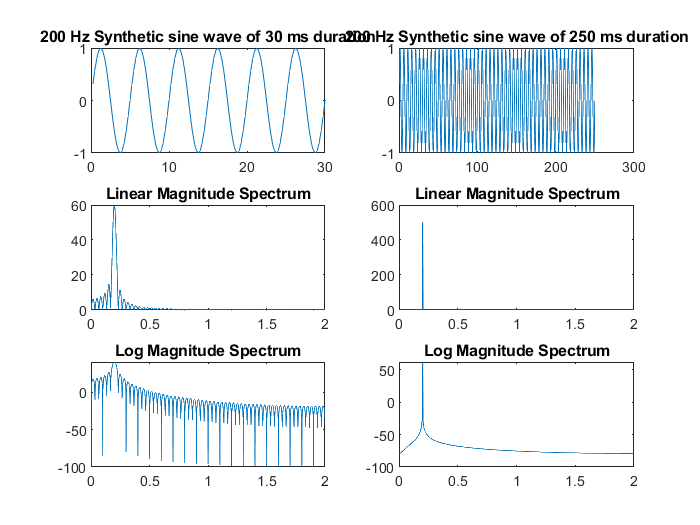

Fs=4000; %sampling frequency
f=200;  %frequency of the sine wave
zero=zeros(1,1000);
t=1/Fs:1/Fs:.03;
y1=sin(2*3.1416*f*t);
subplot(3,2,1);
t=t*1000;
plot(t,y1);
title('200 Hz Synthetic sine wave of 30 ms duration');
y1 = [zero y1 zero];
dfty=abs(fft(y1));
dfty=dfty(1:(length(dfty)/2));
dftylog=10*log(dfty);
ff=linspace(1/Fs,Fs/2000,length(dfty));  
subplot(3,2,3);
plot(ff,dfty);
title('Linear Magnitude Spectrum');
subplot(3,2,5);
plot(ff,dftylog);
title('Log Magnitude Spectrum');

t=1/Fs:1/Fs:.25;
y2=sin(2*3.1416*f*t);
t=t*1000;
subplot(3,2,2);
plot(t,y2);
title('200 Hz Synthetic sine wave of 250 ms duration');
dfty=abs(fft(y2));
dfty=dfty(1:(length(dfty)/2));
dftylog=10*log(dfty);
ff=linspace(1/Fs,Fs/2000,length(dfty));  
subplot(3,2,4);
plot(ff,dfty);
title('Linear Magnitude Spectrum');
subplot(3,2,6);
plot(ff,dftylog);
title('Log Magnitude Spectrum');

**Comments and observations:**

 1) STFT need not accurately represent the true spectral information of speech. 

2) SIne wave of 200 Hz is considers and 30 ms windowed version of it is taken.

3) As it is a single tone stationery signal, we can say that its spectrum will have an impulse only at 200 HZ. And it is observed from the above graph.

4) But, if it's windowed version is taken (30ms) sinc function is obtained as magnitude spectrum.

5) This is because, by multipliying it with a rectangular window in the time domain,  leads to  the convolution of their spectra in the frequency domain. The true spectrum of sine wave is impulse at 200 HZ and that of rectangular window is sinc function. As a result,  the convolved spectrum is a sinc function around 200 HZ 

6) Thus we have to be careful in interpreting the spectral information available in the STFT of speech.What we are observing is only the convolved spectra.

**D. Effect of windowing function and window size on short term spectral analysis:**

- Plot short term log magnitude spectra of a 30 ms voiced speech segment  using a rectangular, hamming and hanning window functions. Compare and write your observations in all the three cases.

Fs = 16000

Fs = 16000

% Hanning window
Frame_size=30;
window_length=Frame_size*fs;
win_hann = dsp.Window('Hanning');
y_e_hann = win_hann(x1);
dfty_hann =abs(fft(y_e_hann));
dfty_hann=dfty_hann(1:(length(dfty_hann)/2));

dfty_hann=10*log(dfty_hann);
f=linspace(1/fs,fs/2000,length(dfty_hann));  
figure;

subplot(2,2,1)
plot(f,dfty_hann);
title('Log magnitude spectrum using hanning window');

win_hamm = dsp.Window('Hamming');
y_e_hamm = win_hamm(x1);
dfty_hamm =abs(fft(y_e_hamm));
dfty_hamm=dfty_hamm(1:(length(dfty_hamm)/2));

dfty_hamm=10*log(dfty_hamm);
f=linspace(1/fs,fs/2000,length(dfty_hamm));  
subplot(2,2,2)
plot(f,dfty_hamm);
title('Log magnitude spectrum using hanning window');

% Rectangular window
Frame_size=30;
window_length=Frame_size*fs;
win_rect = rectwin(window_length);
y_e_rect = x1;
for i=1:length(x1)
  y_e_rect(i)=y_e_rect(i)*win_rect(i);
end
dfty_rect = abs(fft(y_e_rect));

dfty_rect=dfty_rect(1:(length(dfty_rect)/2));

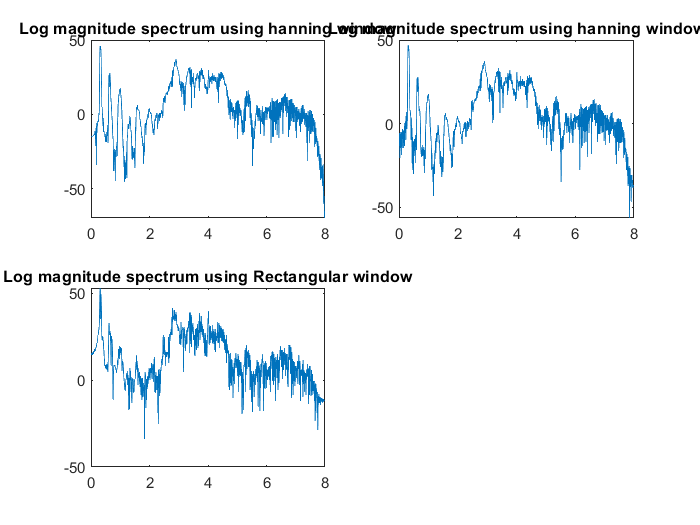

dfty_rect=10*log(dfty_rect);
f=linspace(1/fs,fs/2000,length(dfty_rect));  
subplot(2,2,3)
plot(f,dfty_rect);
title('Log magnitude spectrum using Rectangular window');

**Comments and observations:**

1) The peaks in the log magnitude spectrum of rectangular window are relatively sharper compared to the other cases.

2) However, the spectrum due to the rectangular window seems  to be more noisy compared to the other two window functions. This is because of the high spectral leakage associated with it.( Peak to side lobe ratio of rectanguar window is poor tham other windows.)

3) Because of this leakage, Hamming or hanning window is preferred.

4) Thw width of main lobe in the frequency domain is less for rectangular window is less for rectangular window compared to others. Thus, resolution offered by the rectangular window is better. 

5) Peaks in frequency domain are more prominent in hamming and hanning window.

2. Plot a short term log magnitude spectra of the voiced segment using a frame size of 3 ms, 30 ms and 300 ms. Compare and write your observations in all the three cases.

%Voiced Speech --> 'ee'
t1=0.199*fs : 0.533*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y(t1);
dF1= fs/length(t1); % Time resolution 
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
plot(f1,10*log10(abs(X1)/fs));

xlabel('frequency');

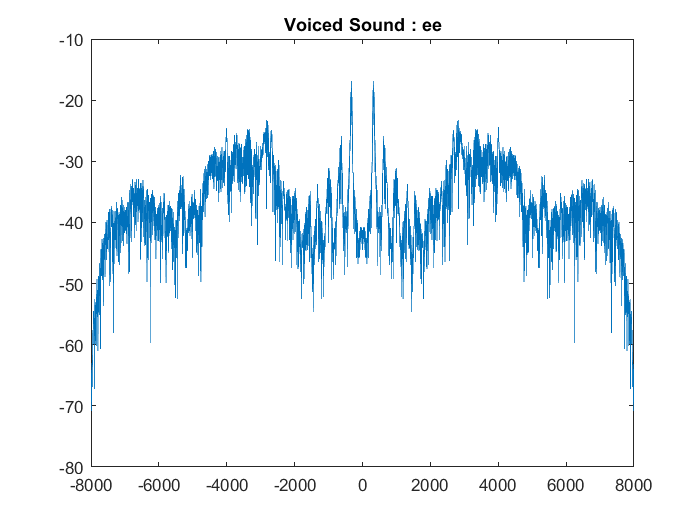

title('Voiced Sound : ee');

%--------------------------Frame size: 3ms -----------------------------%
% Hanning window
Frame_size=3;
window_length=Frame_size*fs;
win_hann = dsp.Window('Hanning');
y_e_hann = win_hann(x1);
dfty_hann =abs(fft(y_e_hann));
dfty_hann=dfty_hann(1:(length(dfty_hann)/2));

dfty_hann=10*log(dfty_hann);
f=linspace(1/fs,fs/2000,length(dfty_hann));  
figure;
subplot(3,1,1)
plot(f,dfty_hann);
title('Frame_size = 3ms : Log magnitude spectrum using hanning window');
win_hamm = dsp.Window('Hamming');
y_e_hamm = win_hamm(x1);
dfty_hamm =abs(fft(y_e_hamm));
dfty_hamm=dfty_hamm(1:(length(dfty_hamm)/2));

dfty_hamm=10*log(dfty_hamm);
f=linspace(1/fs,fs/2000,length(dfty_hamm));  

subplot(3,1,2)
plot(f,dfty_hamm);
title('Log magnitude spectrum using hanning window');

% Rectangular window
window_length=Frame_size*fs;

win_rect = rectwin(window_length);
y_e_rect = x1;
for i=1:length(x1)
  y_e_rect(i)=y_e_rect(i)*win_rect(i);
end

dfty_rect = abs(fft(y_e_rect));
dfty_rect=dfty_rect(1:(length(dfty_rect)/2));

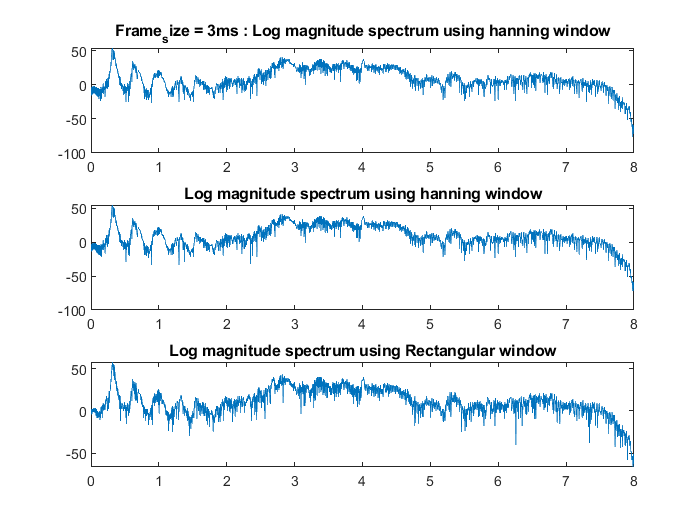

dfty_rect=10*log(dfty_rect);
f=linspace(1/fs,fs/2000,length(dfty_rect));  
subplot(3,1,3)
plot(f,dfty_rect);
title('Log magnitude spectrum using Rectangular window');


%--------------------------Frame size: 30ms -----------------------------%
% Hanning window
Frame_size=30;
window_length=Frame_size*fs;
win_hann = dsp.Window('Hanning');
y_e_hann = win_hann(x1);
dfty_hann =abs(fft(y_e_hann));
dfty_hann=dfty_hann(1:(length(dfty_hann)/2));

dfty_hann=10*log(dfty_hann);
f=linspace(1/fs,fs/2000,length(dfty_hann));  
figure();
subplot(3,1,1)
plot(f,dfty_hann);
title('Frame size = 30ms : Log magnitude spectrum using hanning window');
win_hamm = dsp.Window('Hamming');
y_e_hamm = win_hamm(x1);
dfty_hamm =abs(fft(y_e_hamm));
dfty_hamm=dfty_hamm(1:(length(dfty_hamm)/2));

dfty_hamm=10*log(dfty_hamm);
f=linspace(1/fs,fs/2000,length(dfty_hamm));  

subplot(3,1,2)
plot(f,dfty_hamm);
title('Log magnitude spectrum using hanning window');

% Rectangular window
window_length=Frame_size*fs;

win_rect = rectwin(window_length);
y_e_rect = x1;
for i=1:length(x1)
  y_e_rect(i)=y_e_rect(i)*win_rect(i);
end

dfty_rect = abs(fft(y_e_rect));
dfty_rect=dfty_rect(1:(length(dfty_rect)/2));

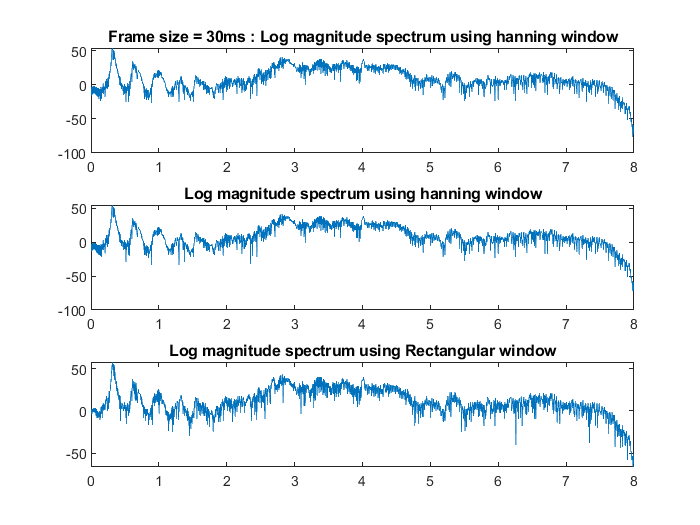

dfty_rect=10*log(dfty_rect);
f=linspace(1/fs,fs/2000,length(dfty_rect));  
subplot(3,1,3)
plot(f,dfty_rect);
title('Log magnitude spectrum using Rectangular window');


%--------------------------Frame size: 300ms -----------------------------%
% Hanning window
Frame_size=300;
window_length=Frame_size*fs;
win_hann = dsp.Window('Hanning');
y_e_hann = win_hann(x1);
dfty_hann =abs(fft(y_e_hann));
dfty_hann=dfty_hann(1:(length(dfty_hann)/2));

dfty_hann=10*log(dfty_hann);
f=linspace(1/fs,fs/2000,length(dfty_hann));  
figure();
subplot(3,1,1)
plot(f,dfty_hann);
title('Frame_size = 300ms : Log magnitude spectrum using hanning window');
win_hamm = dsp.Window('Hamming');
y_e_hamm = win_hamm(x1);
dfty_hamm =abs(fft(y_e_hamm));
dfty_hamm=dfty_hamm(1:(length(dfty_hamm)/2));

dfty_hamm=10*log(dfty_hamm);
f=linspace(1/fs,fs/2000,length(dfty_hamm));  

subplot(3,1,2)
plot(f,dfty_hamm);
title('Log magnitude spectrum using hanning window');

% Rectangular window
window_length=Frame_size*fs;

win_rect = rectwin(window_length);
y_e_rect = x1;
for i=1:length(x1)
  y_e_rect(i)=y_e_rect(i)*win_rect(i);
end

dfty_rect = abs(fft(y_e_rect));
dfty_rect=dfty_rect(1:(length(dfty_rect)/2));

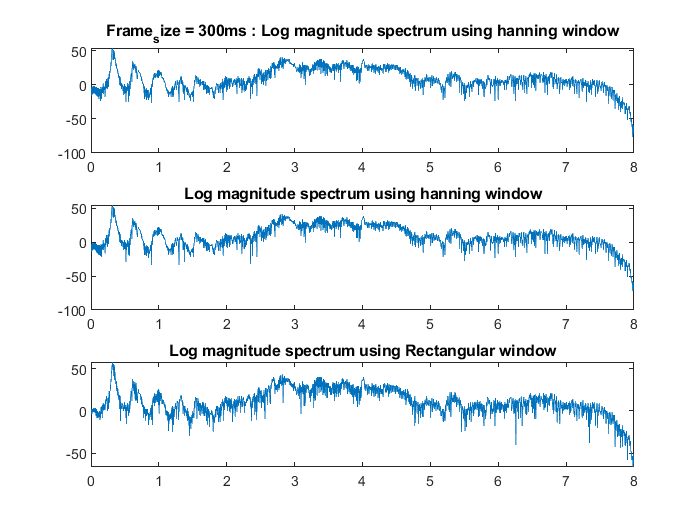

dfty_rect=10*log(dfty_rect);
f=linspace(1/fs,fs/2000,length(dfty_rect));  
subplot(3,1,3)
plot(f,dfty_rect);
title('Log magnitude spectrum using Rectangular window');

Observations and Comments:

 If the window duration is of 10-30 ms, then the spectral information may be affected to a minimum extent. Alternatively, if the window size is too less, then the window effect may be too severe. In yet another case, if the window is too large , say 100 msec, then even though windowing effect is negligable compared to 10-30 ms case, we cannot use such a long window due to the non-stationary nature of speech

1) In case of 30 ms, the log magnitude spectrum contains both the vocal tract information as envelope and the excitation source information in terms of pitch and its harmonics.

2) In case of 3 ms, since the window size is less than a pitch period, the log magnitude spectrum has only smooth envelope representing vocal tract information. However, due very short frame size, the vocal tract information  is affected  from poor spectral resolution.

3) In the 300 ms case, the spectrum suffers from timing resolution due to its large size. .

Functions:

function [c] = stft_(Speech_signal, Fs, Frame_size, Frame_shift, window_type)
y=Speech_signal;
Frame_size=Frame_size/1000;    
Frame_shift=Frame_shift/1000;  
max_value=max(abs(y));
y=y/max_value;
t=1/Fs:1/Fs:(length(y)/Fs);
Frame_length = Frame_size*Fs ;
sample_shift = Frame_shift*Fs ;
w=window(window_type,Frame_length);
jj=1;
for i=1:(floor((length(y))/sample_shift)-ceil(Frame_length/sample_shift))
  k=1;yy=0;
  for j=(((i-1)*sample_shift)+1):(((i-1)*sample_shift)+Frame_length)
    yy(k)=y(j)*w(jj);
    jj=jj+1;k=k+1;
  end
  jj=1;
  dfty=abs(fft(yy)); 
end
c=dfty;
return ;
end

%function to compute 3D short term fourier transform
function [c] = stft3D(Speech_signal, Fs, Frame_size, Frame_shift, window_type)
y=Speech_signal;
Frame_size=Frame_size/1000;    
Frame_shift=Frame_shift/1000;  
max_value=max(abs(y));
y=y/max_value;
t=1/Fs:1/Fs:(length(y)/Fs);
subplot(2,1,1);
plot(t,y);
title('Speech signal waveform');
Frame_length = Frame_size*Fs
sample_shift = Frame_shift*Fs
sum1=0;energy=0;autocorrelation=0;w=window(window_type,Frame_length);jj=1;
for i=1:(floor((length(y))/sample_shift)-ceil(Frame_length/sample_shift))
  k=1;yy=0;
  for j=(((i-1)*sample_shift)+1):(((i-1)*sample_shift)+Frame_length)
    yy(k)=y(j)*w(jj);
    jj=jj+1;k=k+1;
  end
  jj=1;
  dfty=abs(fft(yy));
  dfty3d(:,i)=dfty(1:(length(dfty)/2));  
end
c=dfty3d;
return;
end

%function to compute log magnitude spectrum of a speech segment for a particular window type
function [c] = stft_win(Speech_signal, Fs, window_type,frame_size)
y=Speech_signal; y2=0;
zero=zeros(1,10000);
w=dsp.Window(window_type)
for i=1:length(y)
  y(i)=y(i)*w(i);
end
y2 = [zero y zero];

dfty=abs(fft(y2));
dfty=dfty(1:(length(dfty)/2));
dfty=10*log(dfty);
c=dfty;
return ;
end
